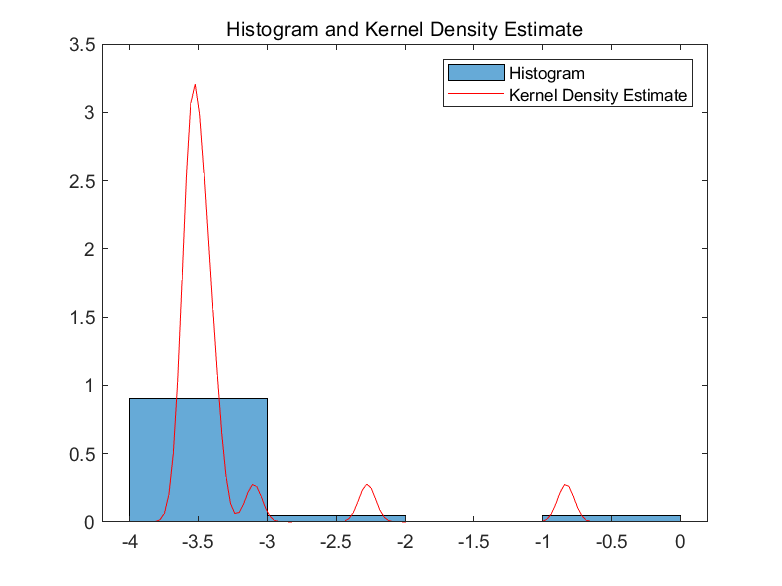

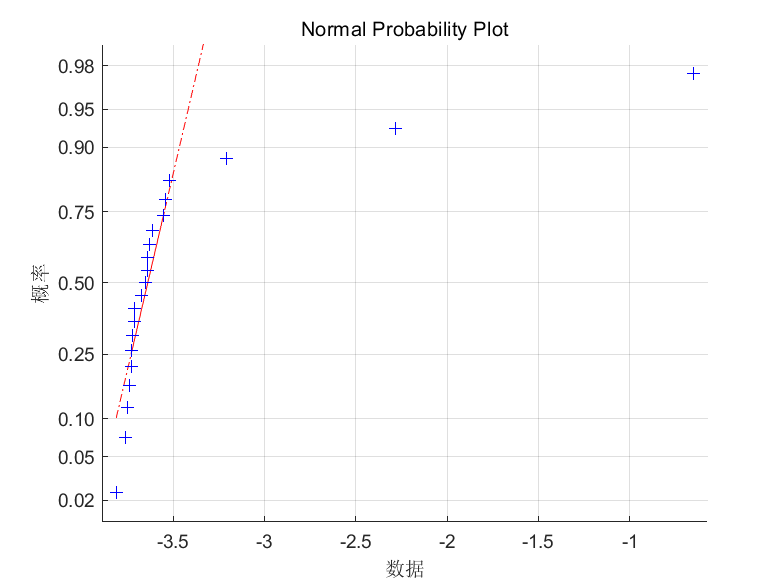

Skewness: 3.20
Kurtosis: 12.45


指标列: 1.00


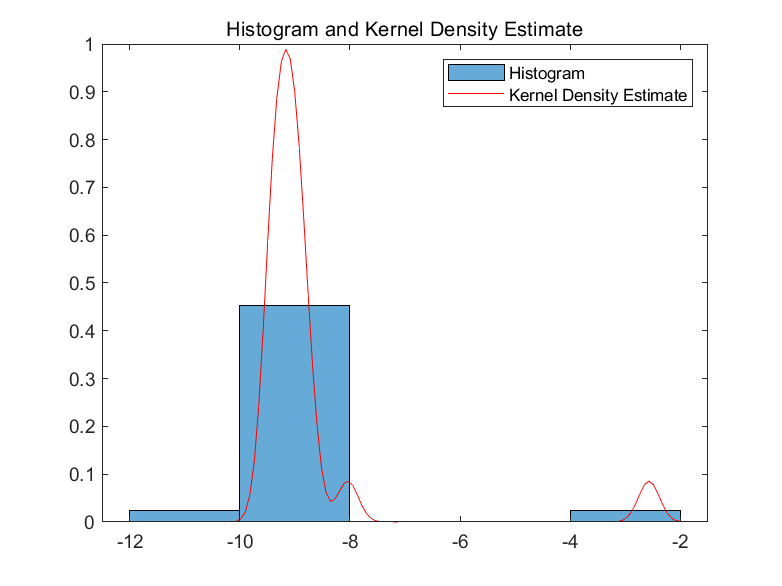

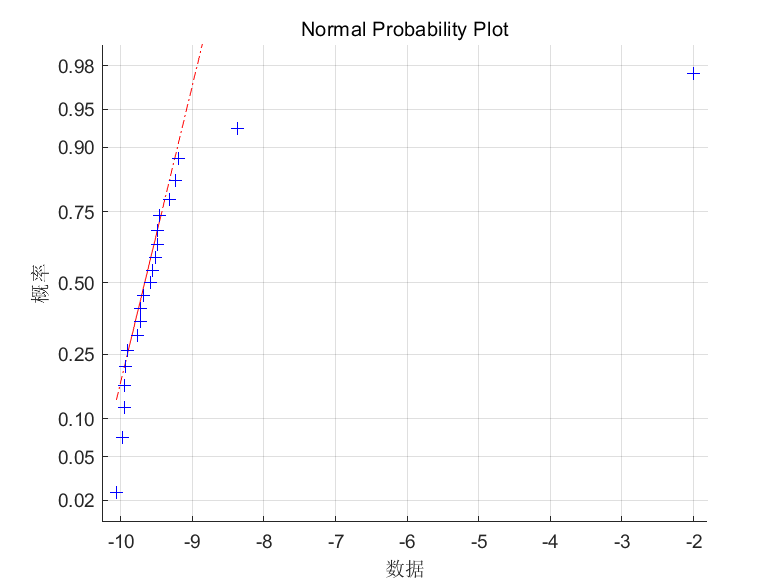

Skewness: 3.93
Kurtosis: 17.25


指标列: 2.00


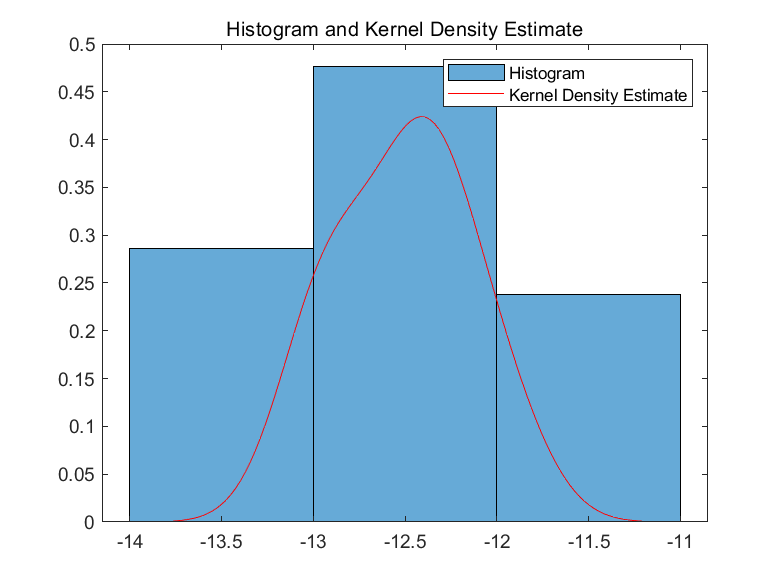

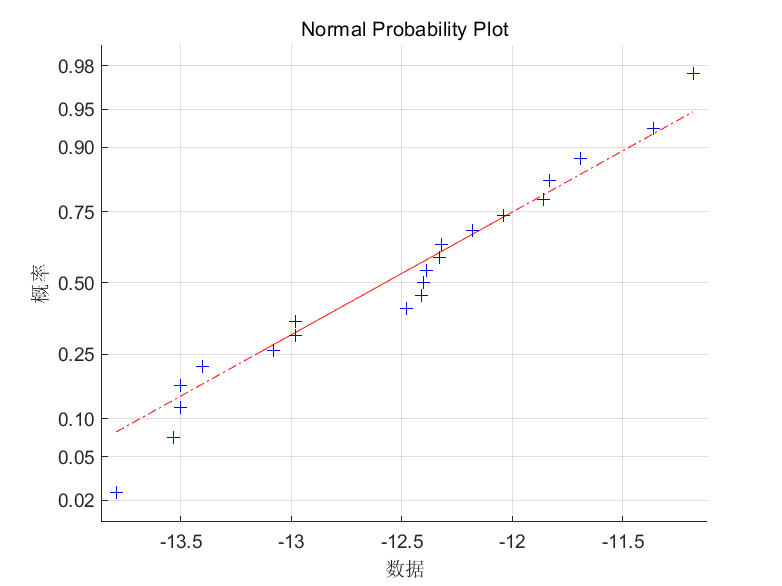

Skewness: -0.02
Kurtosis: 2.02


指标列: 3.00


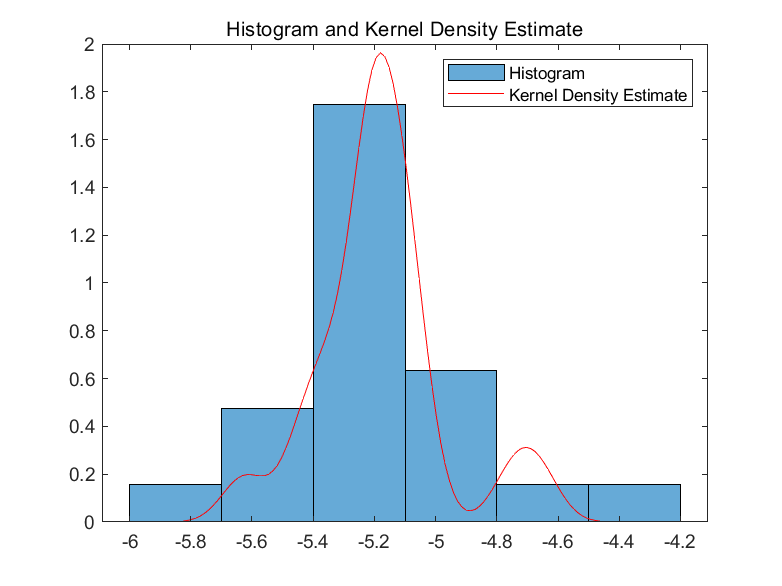

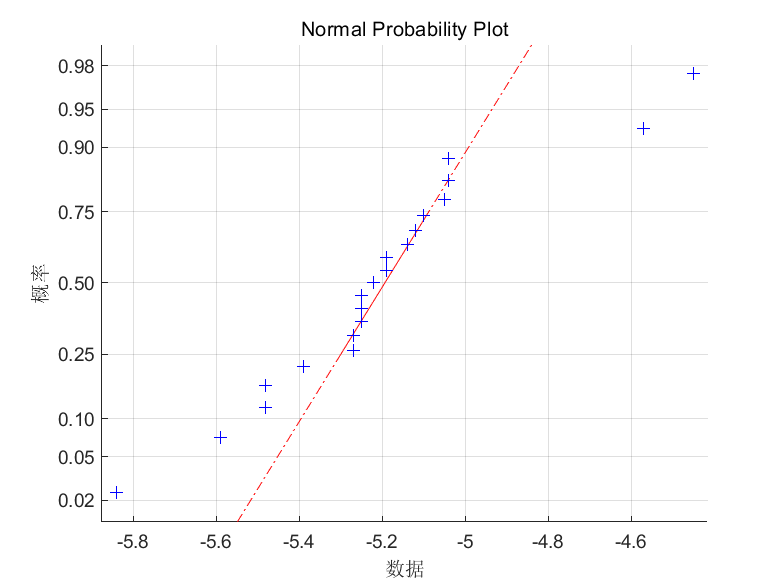

Skewness: 0.57
Kurtosis: 4.28


指标列: 4.00


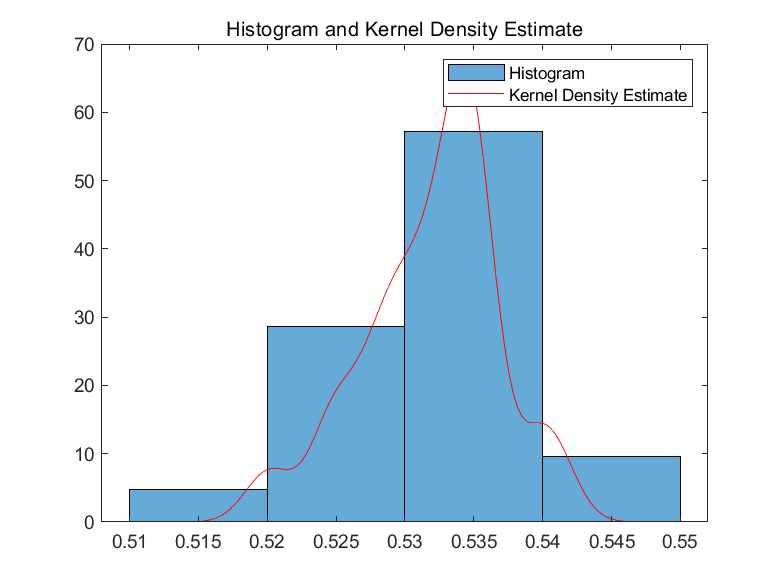

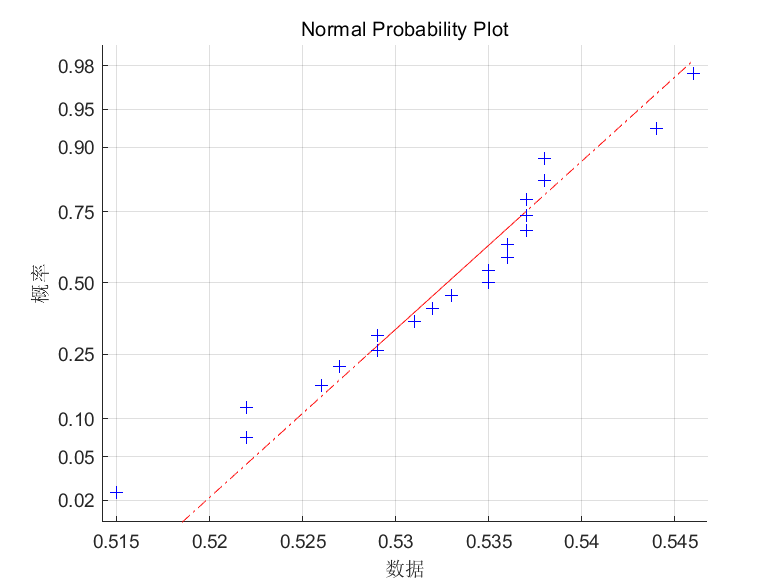

Skewness: -0.49
Kurtosis: 3.08


指标列: 5.00


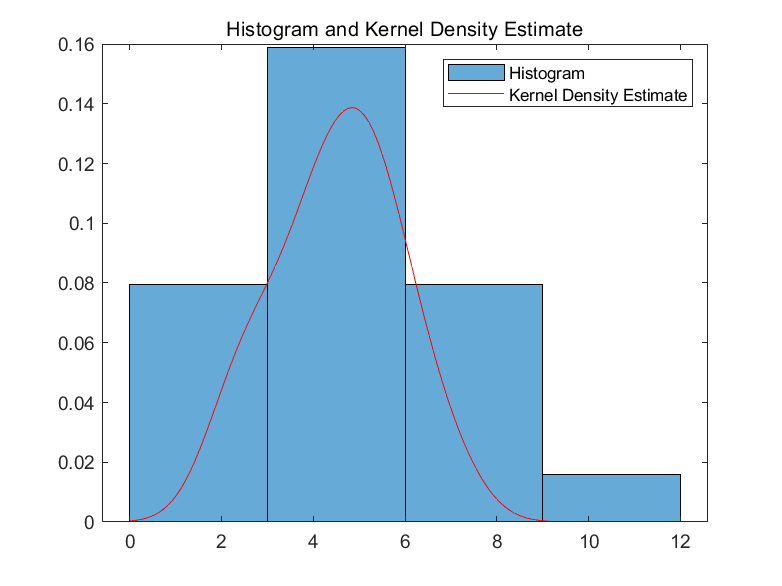

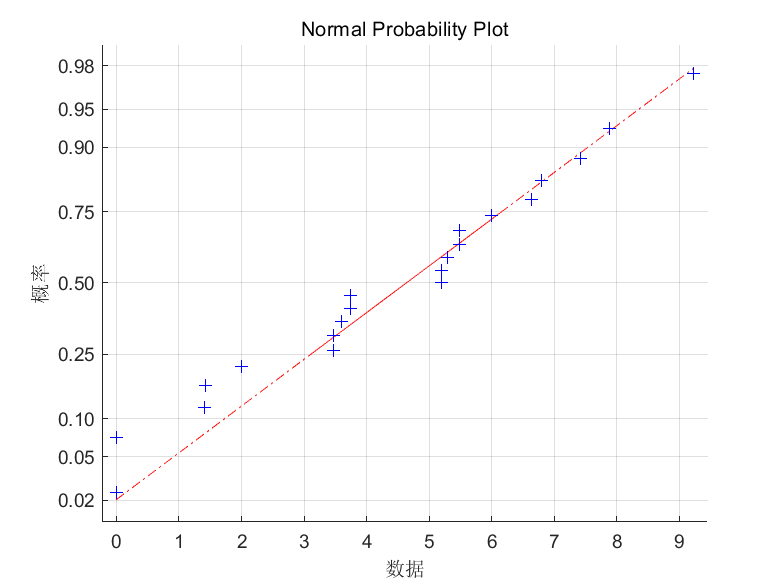

Skewness: -0.14
Kurtosis: 2.31


指标列: 6.00


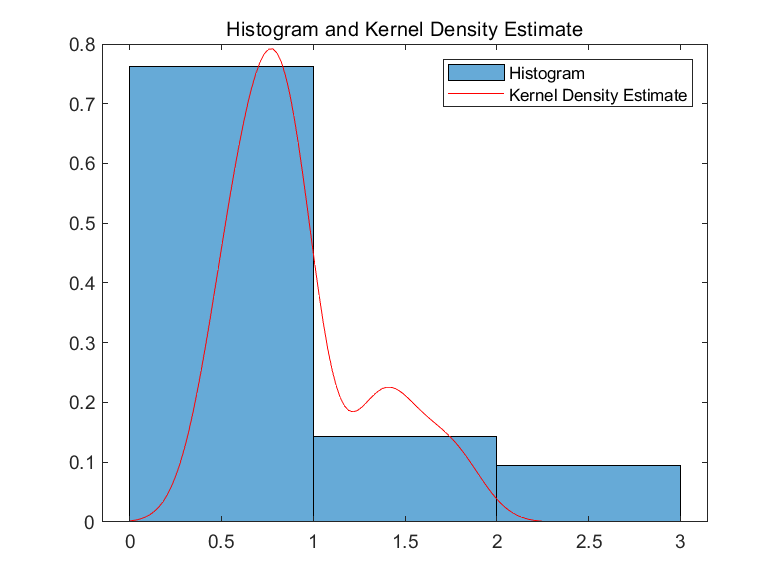

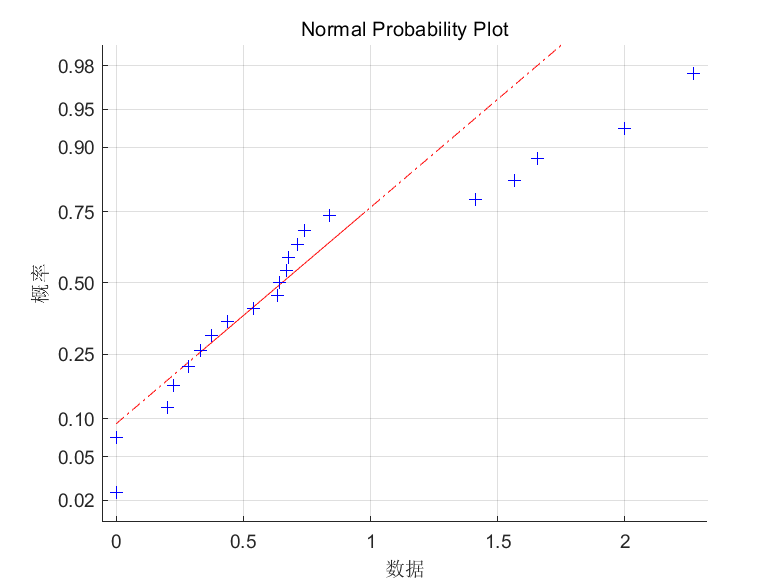

Skewness: 0.99
Kurtosis: 2.97


指标列: 7.00


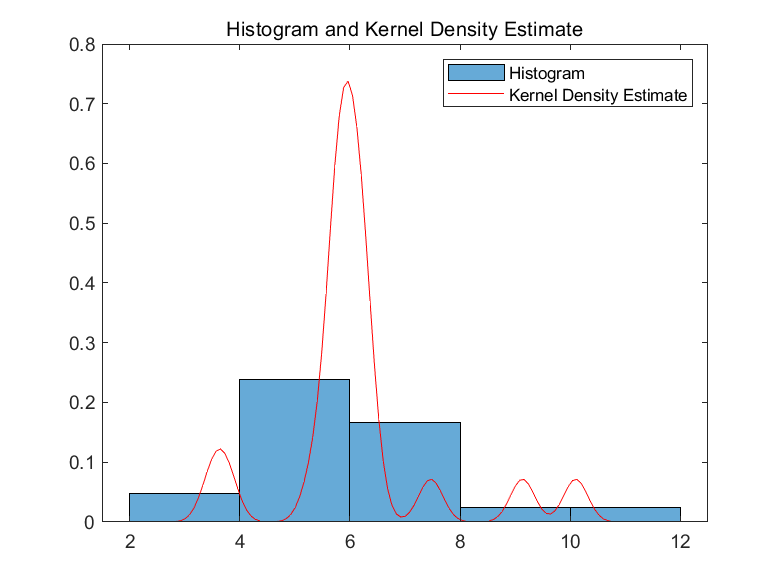

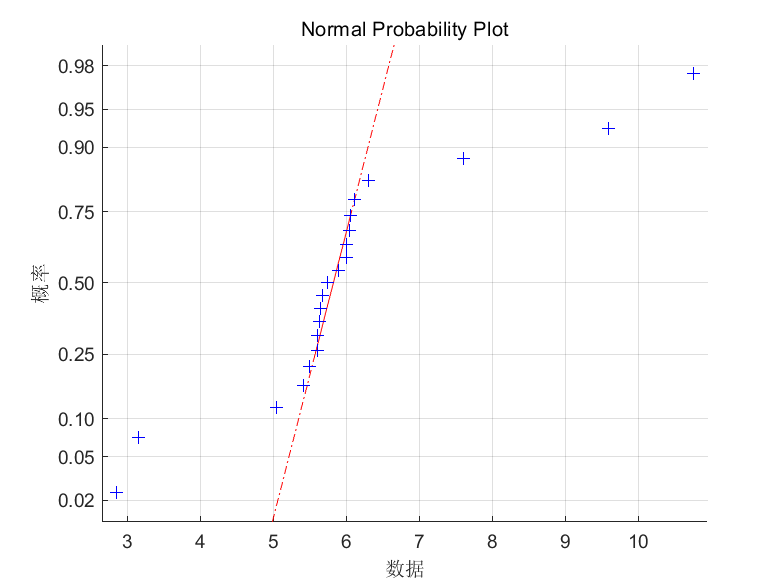

Skewness: 1.03
Kurtosis: 5.19


指标列: 8.00


for i = 1:size(D,2)
    in = D(:,i);
    test(in)
    fprintf('指标列: %.0f\n',i)
end

function test(data)
% 生成1000个服从正态分布的随机数
% data = normrnd(0,1,1000,1);

% 绘制直方图和核密度估计图
figure
histogram(data,'Normalization','pdf')
hold on
f = ksdensity(data);
plot(linspace(min(data),max(data),length(f)),f,'r')
title('Histogram and Kernel Density Estimate')
legend('Histogram','Kernel Density Estimate')

% 绘制正态概率图
figure
normplot(data)
title('Normal Probability Plot')

% 计算偏度和峰度
skew = skewness(data);
kurt = kurtosis(data);
fprintf('Skewness: %.2f\n',skew)
fprintf('Kurtosis: %.2f\n',kurt)
% 通过计算数据的偏度和峰度可以判断数据的分布类型。
% 偏度是数据分布的不对称程度，正态分布的偏度为0；
% 峰度是数据分布的峰态，正态分布的峰度为3。
end